# Autoencoder VLC

## Decodificador neural para sistema com modulação OOK e h definido

### Sistema:

        **  bits -> OOK -> canal VLC FIR inteiro -> ruído AWGN -> receptor neural**

- O receptor neural funciona como a parte "decoder" do autoencoder.

- O transmissor é fixado como modulação OOK:

- bit 0 -> intensidade 0

- bit 1 -> intensidade A

- Nesse sistemas vamos esclher alguns h e posteriormente vamos implementar o h vindo de um modelo de VLC como uma função

clear; clc; close all;

rng(10);

Parâmetros principais:

Ntrain = 200000;              % bits de treinamento
Ntest  = 100000;              % bits de teste
Nval = 50000;                 %bits de validação

A = 1;                        % amplitude OOK
trainEbNo_dB = 18;            % Eb/N0 usado para treinar o receptor neural
EbNoVec_dB = 0:2:30;          % Eb/N0 usado para teste

Resposta ao impulso do canal VLC: (caso queira testar com um canal pré-definido)

% Canal VLC discreto com coeficientes inteiros
% Exemplos:
%hInt = 1;
% hInt = [1 2 1];
% hInt = [3  2.5 0.01 1 0.001];

%hInt = [95 4 1]; % Canal VLC com linha de visada dominante
%hInt = [45 30 15 7 3];  % A componente LoS ainda é a maior, mas as reflexões são relevantes
%hInt = [25 35 25 10 5]; % Canal com LoS fraco e multipercurso/reflexões mais fortes
%hInt = [0.1 35 25 10 5]; % severa obstrução da LOS

### Canal definido pelo modelo VLC com 4 paredes refletindo:

Parâmetros:

params.theta_deg=70;
params.P_total_mW = 20;
params.FOV_deg = 90;
params.Adet = 1e-4;
params.indexLens = 1.5;
params.Tsc=1;
params.room = [2 2 3]           %[lx ly lz] em metros

params = struct with fields:
     theta_deg: 70
    P_total_mW: 20
       FOV_deg: 90
          Adet: 1.0000e-04
     indexLens: 1.5000
           Tsc: 1
          room: [2 2 3]


params.verticalDistance = 2.15; %em m
params.rho = 0.8;
params.C = 3e8 * 1e-9; %em m/ns
params.delta_t_ns = 0.5;
params.tMax_ns = 40;
params.Tsym_ns = params.delta_t_ns; %usado para a discretização de h

% Prâmetros para decidir como compor a função impulso:
params.includeLOS = true;
params.includeNLOS = true;
params.normalize = "sum";     % "sum", "energy" ou "none"

Definição da grade da sala:

%% Posições TX e RX

lx = params.room(1);
ly = params.room(2);
lz = params.room(3);

% Transmissor no centro do teto, como no código original
TP1 = [0 0 lz/2];

% Receptor no chão, use:
 RP = [0 0 -lz/2];

Geração do canal:

[hVLC, tVLC_ns] = generateVLCChannelH_ChannelModelingSlides(params, TP1, RP);

### Escolher qual canal será usado

Normalização do canal e definição da janela:

- Usar o canal abaixo para usar o canal pré-definido nos vetores ou comentá-lo para usar o canal VLC gerado pelo código

%hInt = hInt/sum(hInt);       %Normalização do h : isso faz com que analisemos apenas o ISI, sem considerar o ganho do canal. Manter isso? pq?
%h = double(hInt(:).');        % mantém coeficientes inteiros

- Usar o canal abaixo para VLC gerado pelo código de modelização na sala ou comentá-lo para usar o dos vetores

h = hVLC(:).';

Definição da memória e janela:

Lh = length(h);               % memória do canal
Lwin = Lh;                    % tamanho da janela usada pelo receptor neural %faz sentido usar isso quando usamos um h de um canal de uma sala?


Usar as 3 linhas abaixo para o h definido em vetor:

% fprintf('Canal VLC inteiro h = [');
% fprintf('%g ', hInt);
% fprintf(']\n');

Figura 1: resposta ao impulso do canal VLC com o vetor h definido pelo vetor

% figure;
% stem(0:Lh-1, hInt, 'filled', 'LineWidth', 1.5);
% grid on;
% xlabel('Atraso discreto');
% ylabel('Coeficiente do canal');
% title('Resposta ao impulso do canal VLC com coeficientes inteiros');

Usar o código abaixo para visualizar as informações da função que gera o canal VLC:

disp('Canal VLC discreto gerado:');

Canal VLC discreto gerado:


disp(h);

    0.6323         0         0         0    0.0677    0.1217    0.0813    0.0527    0.0307    0.0100    0.0029    0.0008




disp('Soma dos taps:');

Soma dos taps:


disp(sum(h));

     1




disp('Informações do canal:');

Informações do canal:


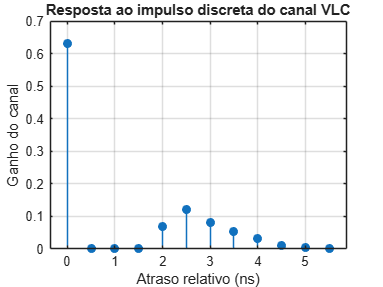


figure;
stem(tVLC_ns, h, 'filled');
grid on;
xlabel('Atraso relativo (ns)');
ylabel('Ganho do canal');
title('Resposta ao impulso discreta do canal VLC');

Gerar dados de treinamento:

bitsTrain = randi([0 1], Ntrain, 1);

% Modulação OOK
xTrain = ookMod(bitsTrain, A);

% Canal VLC + ruído
yTrainClean = filter(h, 1, xTrain);
yTrain = addAwgnFromEbNo(yTrainClean, xTrain, trainEbNo_dB);

% Monta janelas recebidas para o receptor neural
[XTrain, YTrain] = makeVLCWindows(yTrain, bitsTrain, Lwin);


Definição dos dados de validação:

bitsVal = randi([0 1], Nval, 1);

% Modulação OOK
xVal = ookMod(bitsVal, A);

% Canal VLC + ruído
yValClean = filter(h, 1, xVal);
yVal = addAwgnFromEbNo(yValClean, xVal, trainEbNo_dB);

% Monta janelas recebidas para o receptor neural
[XVal, YVal] = makeVLCWindows(yVal, bitsVal, Lwin);

Definição do receptor neural:

numClasses = 2;

layersRx = [
    featureInputLayer(Lwin, "Name", "received_window", "Normalization", "zscore")

    fullyConnectedLayer(32, "Name", "fc1")
    reluLayer("Name", "relu1")

    fullyConnectedLayer(16, "Name", "fc2")
    reluLayer("Name", "relu2")

    fullyConnectedLayer(numClasses, "Name", "fc_out")
    softmaxLayer("Name", "softmax")
    classificationLayer("Name", "class_output")
    ];

Figura2: arquitetura do receptor neural:

figure;
plot(layerGraph(layersRx));

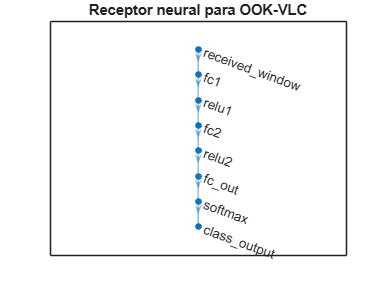

title('Receptor neural para OOK-VLC');

Parâmetros de treinamento:

trainParams.SolverName = "adam";
trainParams.NumEpochs = 8;
trainParams.MiniBatchSize = 512;
trainParams.InitialLearnRate = 1e-3;
trainParams.Shuffle = "every-epoch";
trainParams.TrainingPlot = "training-progress";
trainParams.Verbose = true;
trainParams.ValidationFrequency = 100;

options = trainingOptions(trainParams.SolverName, ...
    "MaxEpochs", trainParams.NumEpochs, ...
    "MiniBatchSize", trainParams.MiniBatchSize, ...
    "InitialLearnRate", trainParams.InitialLearnRate, ...
    "Shuffle", trainParams.Shuffle, ...
    "ValidationData", {XVal, YVal}, ...
    "ValidationFrequency", trainParams.ValidationFrequency, ...
    "Plots", trainParams.TrainingPlot, ...
    "Verbose", trainParams.Verbose);

obs: A loss não é passada explicitamente porque trainNetwork usa um classificationLayer no final da rede. Isso implica que a loss é necessariamente cross-entropy. 

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       32.42% |       36.10% |       0.9260 |       0.8779 |          0.0010 |
|       1 |          50 |       00:00:04 |       83.40% |              |       0.4518 |              |          0.0010 |
|       1 |         100 |       00:00:04 |       98.24% |       98.36% |       0.1801 |       0.1770 |          0.0010 |
|       1 |         150 |       00:00:05 |       99.61% |              |       0.0737 |   

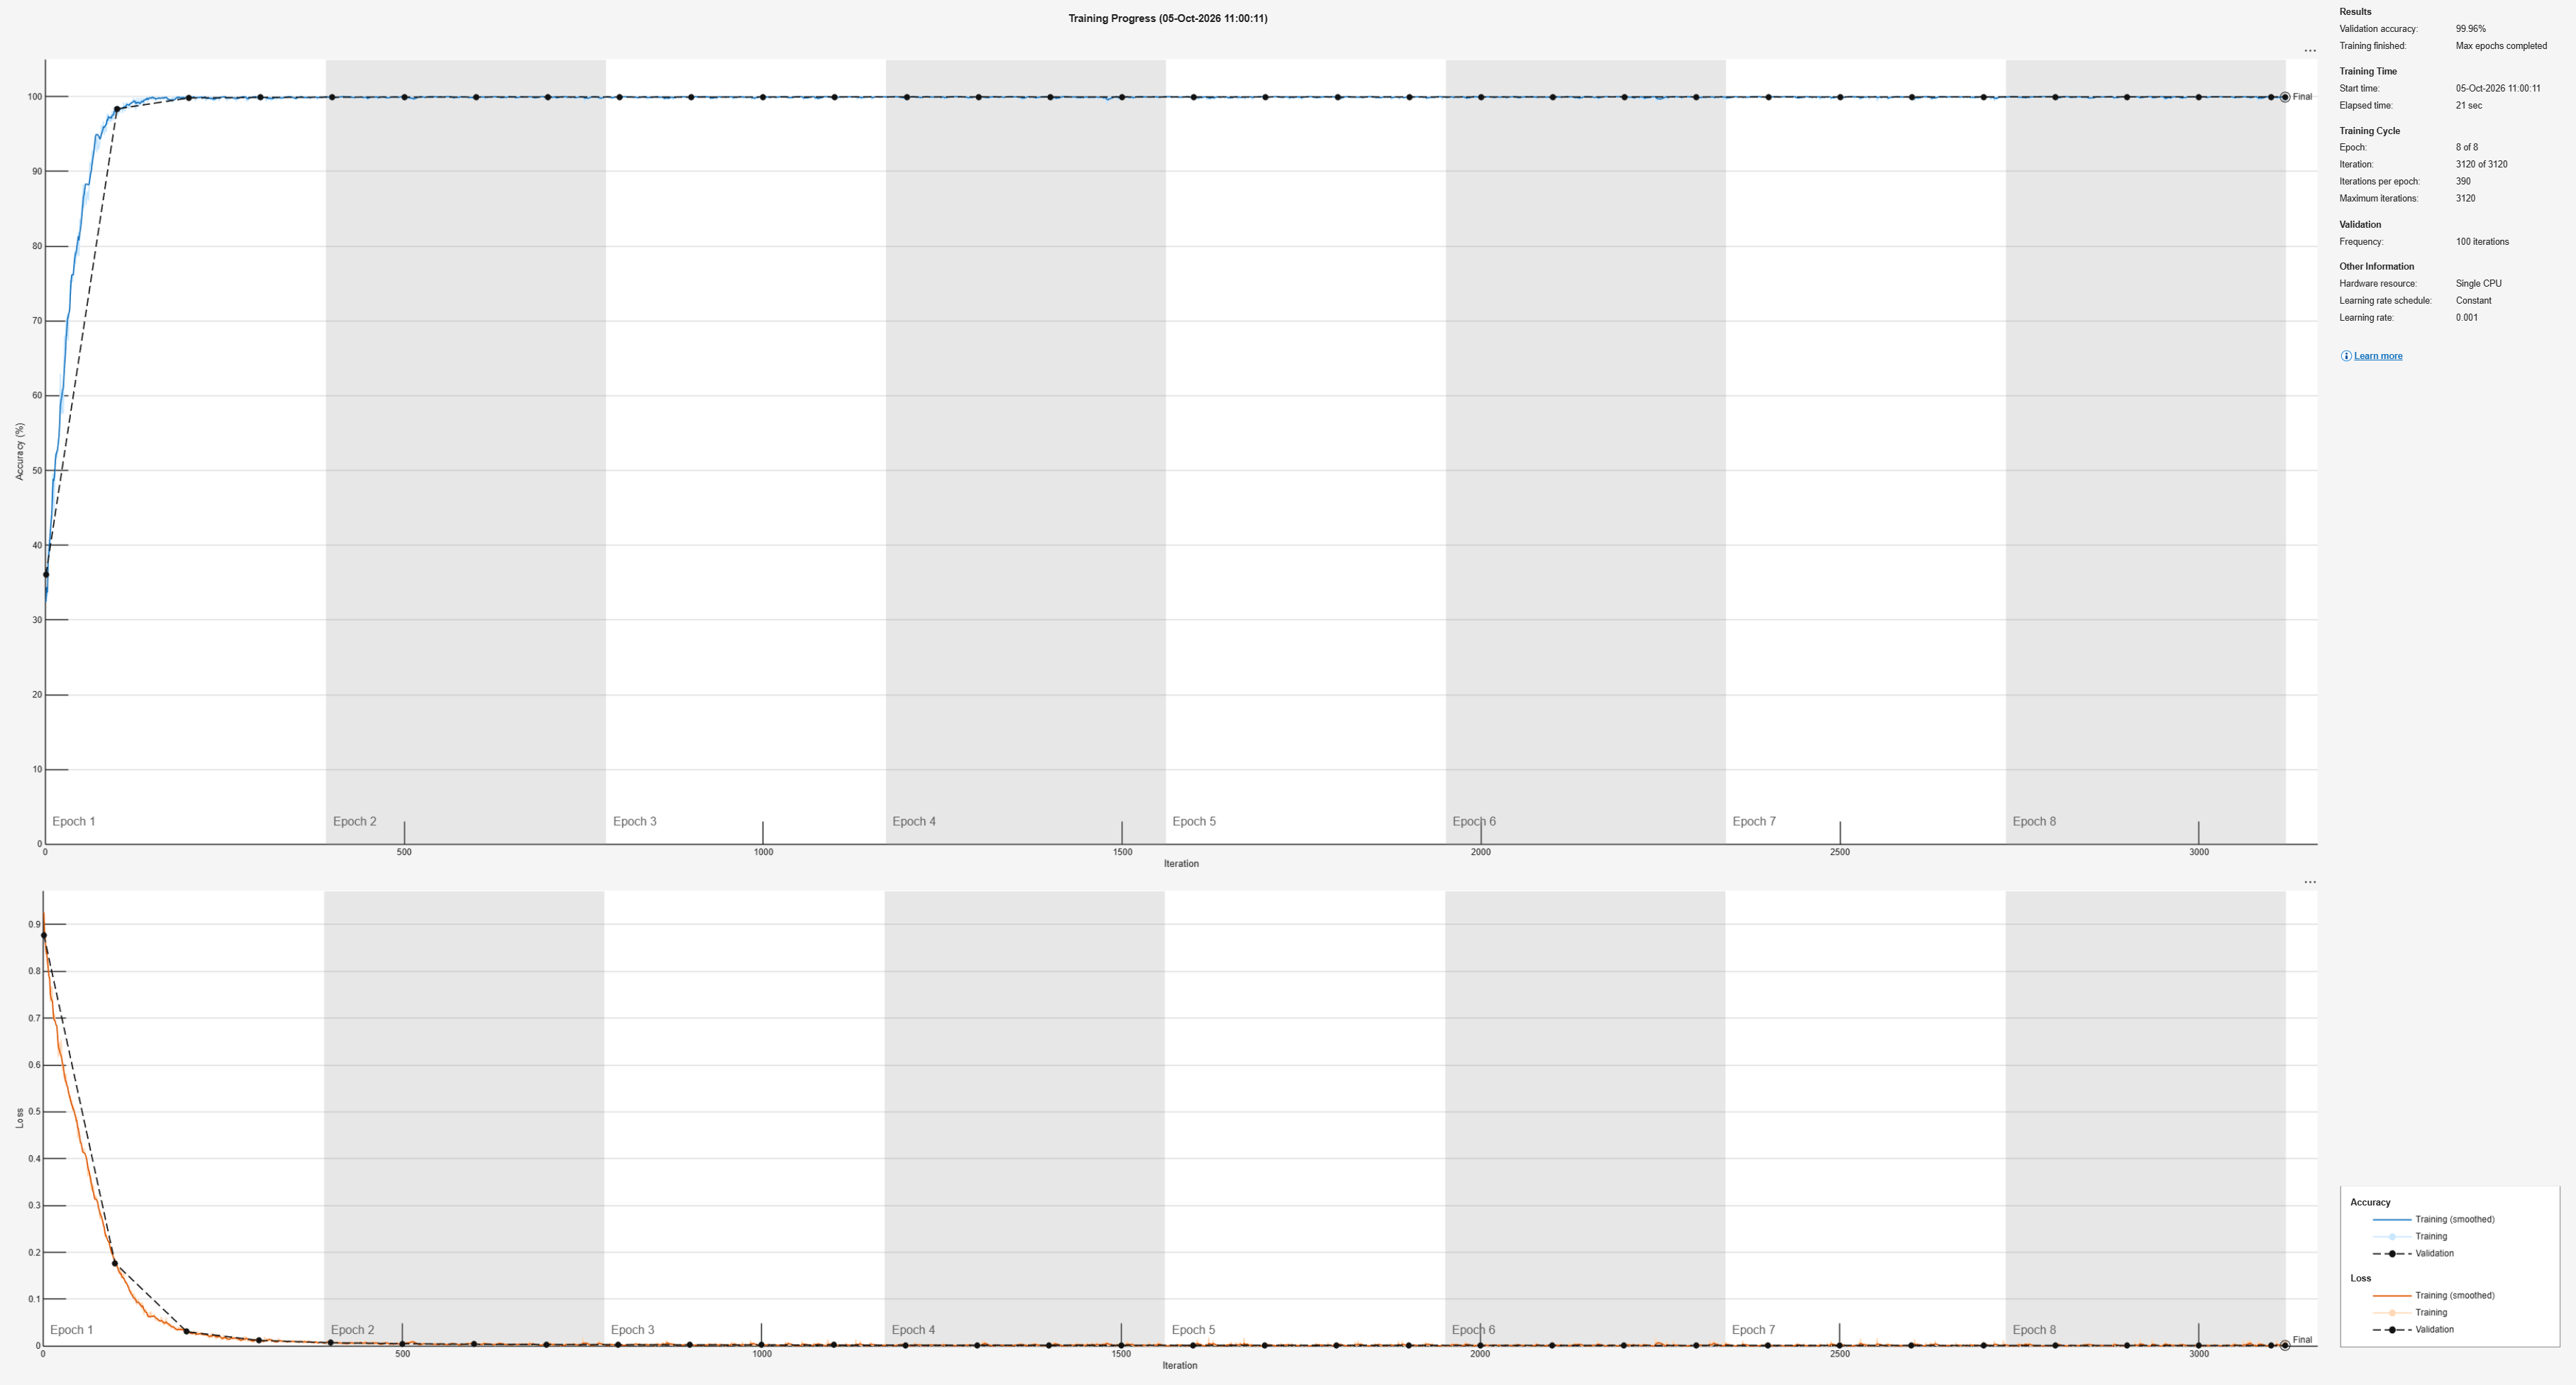

[rxNet, trainInfo] = trainNetwork(XTrain, YTrain, layersRx, options);

### Teste BER do receptor neural e detector clássico

%% Teste: BER do receptor neural e detectores clássicos

BER_Neural = zeros(size(EbNoVec_dB));
BER_ZF = zeros(size(EbNoVec_dB));
BER_Threshold = zeros(size(EbNoVec_dB));

% Atraso associado ao tap dominante do canal.
% Esse atraso é usado para alinhar o detector por limiar com a amostra
% em que a maior parte da energia do bit aparece.
[~, delayIdx] = max(h);
delay = delayIdx - 1;

% Limiar simples.
% Se h foi normalizado por soma, normalmente sum(h)=1.
% Mantemos a forma geral para também funcionar caso h não esteja normalizado.
thresholdSimple = 0.5*A*sum(h);

% Valores desejados de Eb/N0 para salvar em detalhes.
% Esses testes permitem analisar sinais, scores, erros e decisões da rede.
desiredDetailedEbNoVec_dB = [10 20];

% Encontra, em EbNoVec_dB, os índices mais próximos dos valores desejados.
% Isso deixa o código robusto caso o vetor EbNoVec_dB mude no futuro.
detailedIdxVec = zeros(size(desiredDetailedEbNoVec_dB));

for kDetail = 1:length(desiredDetailedEbNoVec_dB)
    [~, detailedIdxVec(kDetail)] = min(abs(EbNoVec_dB - desiredDetailedEbNoVec_dB(kDetail)));
end

% Remove índices repetidos, caso dois valores desejados caiam no mesmo ponto.
detailedIdxVec = unique(detailedIdxVec);

% Valores efetivamente salvos.
detailedEbNoVec_dB = EbNoVec_dB(detailedIdxVec);

% Estrutura para guardar os testes detalhados.
detailedTests = struct([]);
detailedCounter = 0;


for idx = 1:length(EbNoVec_dB)

    EbNo_dB = EbNoVec_dB(idx);

    %% Geração dos dados de teste

    bitsTest = randi([0 1], Ntest, 1);
    xTest = ookMod(bitsTest, A);

    yClean = filter(h, 1, xTest);
    y = addAwgnFromEbNo(yClean, xTest, EbNo_dB);


    %% Receptor neural

    [XTest, YTest] = makeVLCWindows(y, bitsTest, Lwin);

    score = predict(rxNet, XTest);
    [~, idxHat] = max(score, [], 2);

    % Como há duas classes, a coluna 1 corresponde ao bit 0
    % e a coluna 2 corresponde ao bit 1.
    bitsHatNeural = idxHat - 1;

    % Referência correta dos bits usados nas janelas.
    % makeVLCWindows usa bits(1:Nobs), então usamos a mesma referência.
    Nobs = size(XTest, 1);
    bitsRef = bitsTest(1:Nobs);

    BER_Neural(idx) = mean(bitsHatNeural ~= bitsRef);


    %% Detector clássico 1: limiar simples alinhado ao tap dominante

    % O detector por limiar precisa ser alinhado porque o canal FIR
    % pode atrasar a maior contribuição do bit transmitido.
    %
    % Para decidir o bit b(i), usamos y(i+delay), onde delay é a posição
    % do maior coeficiente de h.
    yAligned = y(1+delay : Nobs+delay);

    bitsHatThreshold = yAligned > thresholdSimple;

    BER_Threshold(idx) = mean(bitsHatThreshold ~= bitsRef);


    %% Detector clássico 2: equalizador zero-forcing

    % O equalizador ZF tenta aplicar o filtro inverso 1/H(z).
    % Observação: esta baseline pode amplificar muito o ruído,
    % especialmente quando h(1) é muito pequeno.
    xZF = filter(1, h, y);

    bitsHatZF = xZF > A/2;
    bitsHatZFValid = bitsHatZF(1:Nobs);

    BER_ZF(idx) = mean(bitsHatZFValid ~= bitsRef);


    %% Salva explicitamente os testes escolhidos para análise posterior

    if any(idx == detailedIdxVec)

        detailedCounter = detailedCounter + 1;

        detailedTests(detailedCounter).EbNo_dB = EbNo_dB;

        detailedTests(detailedCounter).bitsTest = bitsTest;
        detailedTests(detailedCounter).bitsRef = bitsRef;

        detailedTests(detailedCounter).xTest = xTest;
        detailedTests(detailedCounter).yClean = yClean;
        detailedTests(detailedCounter).y = y;

        detailedTests(detailedCounter).XTest = XTest;
        detailedTests(detailedCounter).YTest = YTest;

        detailedTests(detailedCounter).score = score;

        detailedTests(detailedCounter).bitsHatNeural = bitsHatNeural;
        detailedTests(detailedCounter).bitsHatThreshold = bitsHatThreshold;
        detailedTests(detailedCounter).bitsHatZF = bitsHatZFValid;

        detailedTests(detailedCounter).BER_Neural = BER_Neural(idx);
        detailedTests(detailedCounter).BER_Threshold = BER_Threshold(idx);
        detailedTests(detailedCounter).BER_ZF = BER_ZF(idx);

        detailedTests(detailedCounter).delay = delay;
        detailedTests(detailedCounter).thresholdSimple = thresholdSimple;

    end

end

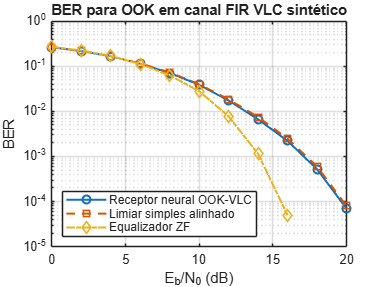

%% Figura 4: BER

figure;
semilogy(EbNoVec_dB, BER_Neural, 'o-', 'LineWidth', 1.5);
hold on;
semilogy(EbNoVec_dB, BER_Threshold, 's--', 'LineWidth', 1.5);
semilogy(EbNoVec_dB, BER_ZF, 'd-.', 'LineWidth', 1.5);

grid on;
xlabel('E_b/N_0 (dB)');
ylabel('BER');

legend('Receptor neural OOK-VLC', ...
    'Limiar simples alinhado', ...
    'Equalizador ZF', ...
    'Location', 'southwest');

title('BER para OOK em canal FIR VLC sintético');

%% Escolha do teste detalhado para as figuras

plotEbNo_dB = 20;   

plotIdx = find([detailedTests.EbNo_dB] == plotEbNo_dB, 1);

if isempty(plotIdx)
    error('O Eb/N0 escolhido para plotagem não foi salvo em detailedTests.');
end

plotTest = detailedTests(plotIdx);

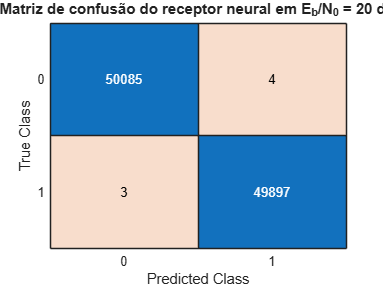

%% Figura 5: matriz de confusão do teste escolhido

figure;
confusionchart(categorical(plotTest.bitsRef), categorical(plotTest.bitsHatNeural));

title(sprintf('Matriz de confusão do receptor neural em E_b/N_0 = %d dB', ...
    plotTest.EbNo_dB));

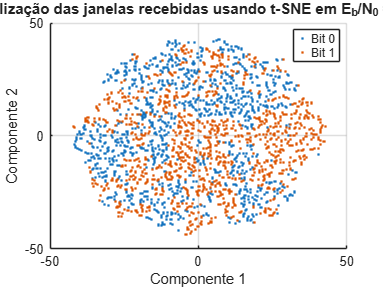

%% Figura 6: visualização das janelas recebidas

numViz = min(3000, size(plotTest.XTest, 1));

Xviz = plotTest.XTest(1:numViz, :);
Yviz = plotTest.bitsRef(1:numViz);

% Caso especial: se Lwin = 1, cada janela tem apenas uma amostra.
% Nesse caso, não é possível obter duas componentes reais via PCA.
if size(Xviz, 2) == 1

    Z = [Xviz(:,1), zeros(size(Xviz,1),1)];
    methodName = 'amostra recebida 1D';

else

    if exist('tsne', 'file') == 2

        Z = tsne(Xviz);
        methodName = 't-SNE';

    elseif exist('pca', 'file') == 2

        [~, Zpca] = pca(Xviz);

        if size(Zpca, 2) >= 2
            Z = Zpca(:,1:2);
        else
            Z = [Zpca(:,1), zeros(size(Zpca,1),1)];
        end

        methodName = 'PCA';

    else

        Z = Xviz(:,1:2);
        methodName = 'amostras brutas';

    end

end

figure;
gscatter(Z(:,1), Z(:,2), Yviz);

grid on;
xlabel('Componente 1');
ylabel('Componente 2');

title(['Visualização das janelas recebidas usando ', methodName, ...
    sprintf(' em E_b/N_0 = %d dB', plotTest.EbNo_dB)]);

legend('Bit 0', 'Bit 1');

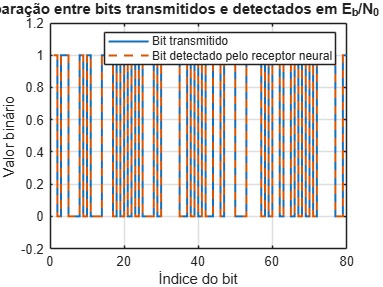

%% Figura 7: comparação visual entre bits transmitidos e detectados

Nshow = min(80, length(plotTest.bitsRef));

figure;
stairs(plotTest.bitsRef(1:Nshow), 'LineWidth', 1.5);
hold on;
stairs(plotTest.bitsHatNeural(1:Nshow), '--', 'LineWidth', 1.5);

grid on;
ylim([-0.2 1.2]);

xlabel('Índice do bit');
ylabel('Valor binário');

legend('Bit transmitido', 'Bit detectado pelo receptor neural');

title(sprintf('Comparação entre bits transmitidos e detectados em E_b/N_0 = %d dB', ...
    plotTest.EbNo_dB));

Funções locais:

function x = ookMod(bits, A)
%Modulação OOK:
%bit 0 -> 0
%bit 1 -> A
x = A*double(bits(:));
end

obs: a função abaixo calcula a variância com relação a energia transmitida e não com relação a energia de yClean (i.e. a energia do sinal após passar pelo canal). Isso faz sentido? Devemos mudar?

function y = addAwgnFromEbNo(yClean, xTx, EbNo_dB)
% Adiciona ruído AWGN real com base em Eb/N0.
%
% Para OOK, usa-se a energia média transmitida por bit:
% Eb = E[x^2].
%
% Como o ruído é real, usa-se sigma^2 = N0/2.

EbNo = 10^(EbNo_dB/10);

Eb = mean(xTx.^2);

N0 = Eb/EbNo;
sigma2 = N0/2;

noise = sqrt(sigma2)*randn(size(yClean));

y = yClean + noise;

end

function [X, Y] = makeVLCWindows(y, bits, Lwin)
% Cria janelas de amostras recebidas para detectar cada bit.
%
% Para um canal FIR causal, a amostra y(n), y(n+1), ..., y(n+Lwin-1)
% contém informação sobre o bit transmitido em n.
%
% Entrada da rede:
% X(i,:) = [y(i), y(i+1), ..., y(i+Lwin-1)]
%
% Saída desejada:
% Y(i) = bit(i)

y = y(:);
bits = bits(:);

N = length(bits);
Nobs = N - Lwin + 1;

X = zeros(Nobs, Lwin);

for i = 1:Nobs
    X(i,:) = y(i:i+Lwin-1).';
end

Y = categorical(bits(1:Nobs));

end


Funções locais para gerar o canal VLC em uma sala:

- Função principal 

function [hFIR, tFIR_ns] = generateVLCChannelH_ChannelModelingSlides(params, TP1, RP)
%GENERATEVLCCHANNELH_CHANNELMODELINGSLIDES
%
% Gera apenas o canal VLC discreto hFIR, baseado no código ChannelModelingSlides.mlx.
%
% Uso:
%
%   [hFIR, tFIR_ns] = generateVLCChannelH_ChannelModelingSlides(params, TP1, RP);
%
% Saídas:
%
%   hFIR
%       Canal discreto final usado no receptor neural:
%
%           y = filter(hFIR, 1, x);
%
%   tFIR_ns
%       Vetor de atrasos relativos associados aos taps de hFIR.
% Obs: aqui não consideramos uma grade de recepção, mas um ponto específico
%  definido por RP

    %% ============================================================
    %  1. Parâmetros derivados de parâmetros anteriores
    % =============================================================

    % Ordem Lambertiana do LED
    m = -log10(2)/log10(cosd(params.theta_deg));

    % Field of View em radianos
    FOV = deg2rad(params.FOV_deg);

    % Ganho do concentrador óptico - não estamos usando porque usamos lens
    % (abordagem indicada no código dos slides da aula)
    G_Con = (params.indexLens^2)/(sin(FOV)^2);

    % Tempo de símbolo usado para formar o canal discreto final.
    % Se não for definido, assume que cada tap corresponde à resolução física.
    if isfield(params, 'Tsym_ns')
        Tsym_ns = params.Tsym_ns;
    else
        Tsym_ns = params.delta_t_ns;
    end


    %% ============================================================
    %  2. Discretização da sala e da parede
    % =============================================================

    [x, y, z, Nx, Ny, Nz, dA] = discretizeWall_ChannelModelingSlides(params);


    %% ============================================================
    %  3. Inicialização temporal do canal
    % =============================================================

    % Vetor de tempo físico, em ns.
    t_vector = 0:params.delta_t_ns:params.tMax_ns;

    % Resposta ao impulso 
    h_vector = zeros(1, length(t_vector));


    %% ============================================================
    %  4. Componente LOS
    % =============================================================

    if params.includeLOS

        % Distância TX -> RX
        D1 = sqrt(dot(TP1 - RP, TP1 - RP));

        % Distância vertical real entre transmissor e receptor
        verticalDistance = abs(TP1(3) - RP(3));

        % Modelo simplificado alinhado:
        % phi = psi, então cos^m(phi)*cos(psi) = cos^(m+1)(phi)
        cosphi = verticalDistance/D1;

        % Atraso LOS, em ns
        tau0 = D1/params.C;

        % Condição de FOV
        if abs(acos(cosphi)) <= FOV

            % Ganho do canal LOS
            H_LOS = (m+1)*params.Tsc * G_Con*params.Adet.*cosphi.^(m+1)./(2*pi.*D1.^2);

            % Adiciona a contribuição LOS ao vetor h_vector
            h_vector = addPathLinear_ChannelModelingSlides( ...
                h_vector, H_LOS, tau0, params.delta_t_ns);

        end

    end


    %% ============================================================
    %  5. Componente NLOS - primeira reflexão
    % =============================================================
    %
    % Mantemos a parede do código original:
    %
    %   WP = [-lx/2, y(kk), z(ll)]
    %
    % Como lx = params.room(1), usamos:
    %
    %   -params.room(1)/2

    if params.includeNLOS

            lx = params.room(1);
            ly = params.room(2);
            lz = params.room(3);

            %% Parede 1: x = -lx/2

            dA_xwall = ly*lz/(Ny*Nz);

            for kk = 1:Ny
                for ll = 1:Nz

                    WP = [-lx/2, y(kk), z(ll)];

                    h_vector = addSingleNLOSPath_ChannelModelingSlides( ...
                        h_vector, params, TP1, RP, WP, dA_xwall, m, FOV,G_Con, "x");

                end
            end


            %% Parede 2: x = +lx/2

            for kk = 1:Ny
                for ll = 1:Nz

                    WP = [lx/2, y(kk), z(ll)];

                    h_vector = addSingleNLOSPath_ChannelModelingSlides( ...
                        h_vector, params, TP1, RP, WP, dA_xwall, m, FOV,G_Con, "x");

                end
            end


            %% Parede 3: y = -ly/2

            dA_ywall = lx*lz/(Nx*Nz);

            for kk = 1:Nx
                for ll = 1:Nz

                    WP = [x(kk), -ly/2, z(ll)];

                    h_vector = addSingleNLOSPath_ChannelModelingSlides( ...
                        h_vector, params, TP1, RP, WP, dA_ywall, m, FOV,G_Con, "y");

                end
            end


            %% Parede 4: y = +ly/2

            for kk = 1:Nx
                for ll = 1:Nz

                    WP = [x(kk), ly/2, z(ll)];

                    h_vector = addSingleNLOSPath_ChannelModelingSlides( ...
                        h_vector, params, TP1, RP, WP, dA_ywall, m, FOV, G_Con,"y");

                end
            end
     end


    %% ============================================================
    %  6. Corte dos zeros iniciais e finais
    % =============================================================

    [h_vector_trim, ~, ~] = trimImpulse_ChannelModelingSlides(h_vector, t_vector);


    %% ============================================================
    %  7. Conversão para canal discreto final
    % =============================================================

    samplesPerSymbol = round(Tsym_ns/params.delta_t_ns);

    if samplesPerSymbol < 1
        error('params.Tsym_ns deve ser maior ou igual a params.delta_t_ns.');
    end

    if abs(samplesPerSymbol*params.delta_t_ns - Tsym_ns) > 1e-9
        warning(['params.Tsym_ns não é múltiplo exato de params.delta_t_ns. ', ...
                 'A função usará samplesPerSymbol = %d.'], samplesPerSymbol);
    end

    h_before_norm = physicalToSymbol_ChannelModelingSlides( ...
        h_vector_trim, samplesPerSymbol);

    % Atraso relativo dos taps finais
    tFIR_ns = (0:length(h_before_norm)-1) * Tsym_ns;


    %% ============================================================
    %  8. Normalização
    % =============================================================

    switch string(params.normalize)

        case "none"

            hFIR = h_before_norm;

        case "sum"

            if sum(h_before_norm) > 0
                hFIR = h_before_norm/sum(h_before_norm);
            else
                hFIR = h_before_norm;
            end

        case "energy"

            if sum(h_before_norm.^2) > 0
                hFIR = h_before_norm/sqrt(sum(h_before_norm.^2));
            else
                hFIR = h_before_norm;
            end

        otherwise

            error('params.normalize deve ser "none", "sum" ou "energy".');

    end

end

- Função de discretização da parede

function [x, y, z, Nx, Ny, Nz, dA] = discretizeWall_ChannelModelingSlides(params)
%DISCRETIZEWALL_CHANNELMODELINGSLIDES
%
% Cria a discretização espacial da sala e da parede usada no cálculo NLOS.
    
    Nx = params.room(1)*5;
    Ny = params.room(2)*5;
    Nz = params.room(3)*5;
    
    x = linspace(-params.room(1)/2, params.room(1)/2, Nx);
    y = linspace(-params.room(2)/2, params.room(2)/2, Ny);
    z = linspace(-params.room(3)/2, params.room(3)/2, Nz);
    
    % Área de cada elemento da parede x = -lx/2.
    dA = params.room(3)*params.room(2)/(Ny*Nz);

end

function h_vector = addPathLinear_ChannelModelingSlides(h_vector, H_path, tau, delta_t)
%ADDPATHLINEAR_CHANNELMODELINGSLIDES
%
% Adiciona uma contribuição de caminho óptico ao vetor h_vector usando
% interpolação linear entre bins temporais.

    pos = tau/delta_t + 1;
    
    idxLow = floor(pos);
    idxHigh = idxLow + 1;
    
    alpha = pos - idxLow;
    
    if idxLow >= 1 && idxLow <= length(h_vector)
        h_vector(idxLow) = h_vector(idxLow) + (1-alpha)*H_path;
    end
    
    if idxHigh >= 1 && idxHigh <= length(h_vector)
        h_vector(idxHigh) = h_vector(idxHigh) + alpha*H_path;
    end

end


function [h_trim, t_trim, firstDelay] = trimImpulse_ChannelModelingSlides(h_vector, t_vector)
%TRIMIMPULSE_CHANNELMODELINGSLIDES
%
% Remove zeros iniciais e finais da resposta ao impulso física.

    if all(h_vector == 0)

    h_trim = h_vector;
    t_trim = t_vector;
    firstDelay = 0;
    return;

    end

    threshold = max(abs(h_vector))*1e-12;
    
    idx = find(abs(h_vector) > threshold);
    
    idxStart = idx(1);
    idxEnd = idx(end);
    
    h_trim = h_vector(idxStart:idxEnd);
    t_trim = t_vector(idxStart:idxEnd);
    
    firstDelay = t_trim(1);

end

function h_sym = physicalToSymbol_ChannelModelingSlides(h_phys, samplesPerSymbol)
%PHYSICALTOSYMBOL_CHANNELMODELINGSLIDES
%
% Converte a resposta física h_phys em um canal discreto compatível
% com a sequência de símbolos do código atual.

    h_phys = h_phys(:).';
    
    Lphys = length(h_phys);
    Lsym = ceil(Lphys/samplesPerSymbol);
    
    h_sym = zeros(1, Lsym);
    
    for ii = 1:Lsym
    
        idxStart = (ii-1)*samplesPerSymbol + 1;
        idxEnd = min(ii*samplesPerSymbol, Lphys);
    
        h_sym(ii) = sum(h_phys(idxStart:idxEnd));
    
    end

end


Função que calcula h_NLOS para uma única parede da sala:

function h_vector = addSingleNLOSPath_ChannelModelingSlides( ...
    h_vector, params, TP1, RP, WP, dA, m, FOV,G_Con, wallAxis)

%ADDSINGLENLOSPATH_CHANNELMODELINGSLIDES
%
% Calcula a contribuição TX -> parede -> RX para um único patch WP.

%% TX -> WALL

D_tx_wall = sqrt(dot(TP1 - WP, TP1 - WP));

if D_tx_wall == 0
    return;
end

cos_phi_tx_wall = abs(WP(3) - TP1(3)) / D_tx_wall;

if wallAxis == "x"
    cos_alpha_wall = abs(TP1(1) - WP(1)) / D_tx_wall;
elseif wallAxis == "y"
    cos_alpha_wall = abs(TP1(2) - WP(2)) / D_tx_wall;
else
    error('wallAxis deve ser "x" ou "y".');
end


%% WALL -> RX

D_wall_rx = sqrt(dot(WP - RP, WP - RP));

if D_wall_rx == 0
    return;
end

if wallAxis == "x"
    cos_beta_wall = abs(WP(1) - RP(1)) / D_wall_rx;
elseif wallAxis == "y"
    cos_beta_wall = abs(WP(2) - RP(2)) / D_wall_rx;
end

cos_psi_wall_rx = abs(WP(3) - RP(3)) / D_wall_rx;

cos_psi_wall_rx = max(min(cos_psi_wall_rx, 1), -1);


%% FOV

if abs(acos(cos_psi_wall_rx)) <= FOV

    H_patch = (m+1)*params.Tsc * G_Con*params.Adet*params.rho*dA * ...
        (cos_phi_tx_wall^m) * ...
        cos_alpha_wall * ...
        cos_beta_wall * ...
        cos_psi_wall_rx / ...
        (2*pi^2 * D_tx_wall^2 * D_wall_rx^2);

    tau_NLOS = (D_tx_wall + D_wall_rx)/params.C;

    h_vector = addPathLinear_ChannelModelingSlides( ...
        h_vector, H_patch, tau_NLOS, params.delta_t_ns);

end

end